## Display the range of a matrix A

A=[1 3 3; 2 6 9; -1 -3 3];
disp(A)

     1     3     3
     2     6     9
    -1    -3     3



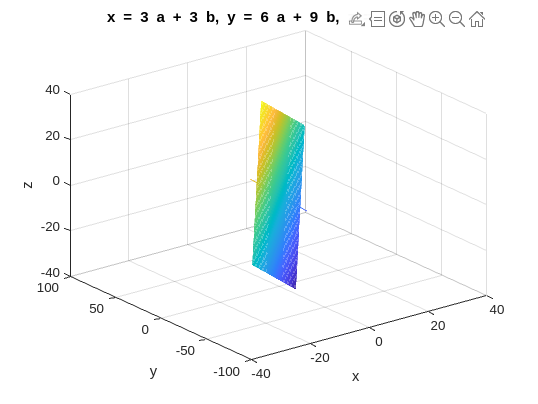

p1=A(:,[1 3])*[a b]';
ezmesh(p1(1),p1(2),p1(3)); hold on;
p2=A(:,[2 3])*[a b]';
ezmesh(p2(1),p2(2),p2(3)); hold on;

## Example of linearly dependent vectors

A=[1 3 3; 2 6 9; -1 -3 3]

A =      1     3     3
     2     6     9
    -1    -3     3


N=null(A); N'

ans =    -0.9487    0.3162         0



%Linear combination of the columns in A
N(1)*A(:,1)+N(2)*A(:,2)+N(3)*A(:,3) %numbers so small that we consider them as zero

ans = 1.0e-15 *

   -0.1110
   -0.2220
    0.1110


A*N

ans = 1.0e-15 *

   -0.1110
   -0.2220
    0.1110


## Matrix rank and Row-reduced echelon form

A=[1 3 3; 2 6 9; -1 -3 3]

A =      1     3     3
     2     6     9
    -1    -3     3


rank(A)

ans = 2

rref(A) % it has the shape of a gaussian elimination matrix

ans =      1     3     0
     0     0     1
     0     0     0


A=[1 3 3; 2 6 9; -1 -3 3]

A =      1     3     3
     2     6     9
    -1    -3     3


[L,U,P]=lu(A);
disp(U)

    2.0000    6.0000    9.0000
         0         0   -1.5000
         0         0    7.5000

